# Filtering, Convolution, Spectrograms

*Bart Krekelberg - Last Update Jan 2023.*

*Data are often contaminated by known artifacts, or nuisance signals. Preprocessing of the signals will help to zoom in on those aspects that are likely to provide useful information. Filters, convolution, and Fourier spectral analysis play an important role in the signal processing.*

## Filtering is multiplication in the Fourier Domain

To understand what filtering is, let's return to the BOLD data from the first MLX file on spectral analysis.

These data are from an fMRI experiment in which a subject viewed images of faces for 16 seconds, followed by images of houses for 16 seconds. Such blocks were repeated several times, and we are showing the BOLD signal in one voxel in the fusiform face area:

First, we load the data and determine the amplitude spectrum

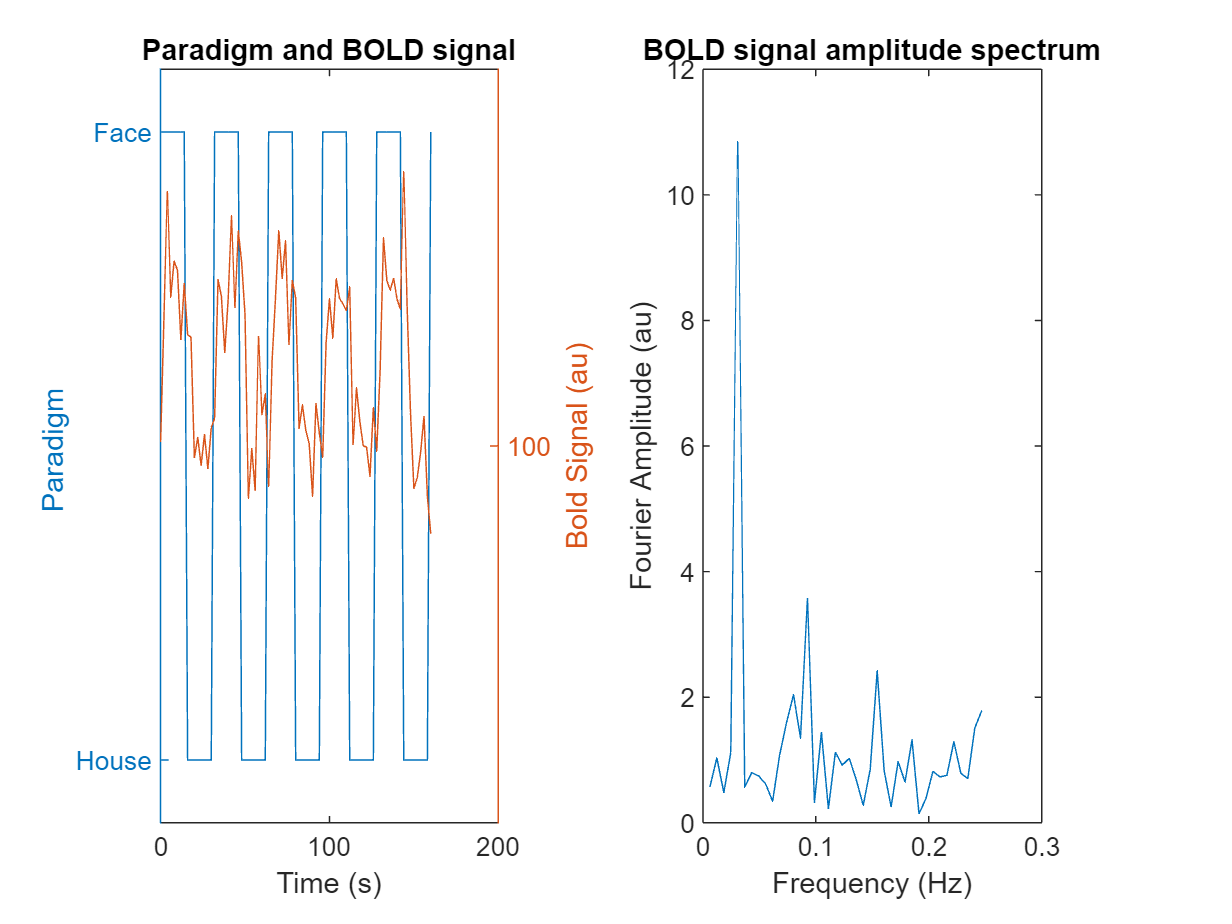

load ../data/boldData


boldFourierComponents = fft(bold); % Get the Fourier components. 
meanBold = boldFourierComponents(1);
nrSamples =length(bold);
sampleTime = TR; % Time between samples is the TR.
samplingRate = (1./sampleTime);
if rem(nrSamples,2)==0
    % Even number of samples. Nyquist is the highest one
    frequency = [0 1:nrSamples/2 (nrSamples/2-1):-1:1]*samplingRate/nrSamples;  
    [~,highestFrequencyIx] =max(frequency);
else
    % Odd number of samples. Nyquist is not in the set.
    frequency = [0 1:(nrSamples-1)/2 (nrSamples-1)/2:-1:1]*samplingRate/nrSamples;
    [~,highestFrequencyIx] =max(frequency);
end

keep = 2:highestFrequencyIx;
halfFrequency = frequency(keep);
halfAmplitudeSpectrum = abs(boldFourierComponents(keep));


figure(1);
clf;
R=1;C=2;
subplot(R,C,1);
yyaxis  left
plot(boldTime,paradigm);
xlabel 'Time (s)'
ylabel('Paradigm ');
set(gca,'YLim',[-0.1 1.1],'YTick',[0 1],'YTickLabel',{'House','Face'})
yyaxis right
plot(boldTime,bold);
ylabel('Bold Signal (au)');
set(gca,'YLim',[99 101],'YTick',100)
title 'Paradigm and BOLD signal'
subplot(R,C,2);
plot(halfFrequency,halfAmplitudeSpectrum);
xlabel 'Frequency (Hz)'
ylabel('Fourier Amplitude (au)');
title 'BOLD signal amplitude spectrum'

As we discussed previously, you can see the stimulus dependent modulation reflected in the peak of the amplitude spectrum at 0.03 Hz.

However, you can also see that there is a lot of power at higher frequencies. Becuase we know from our experimental design that there is no variation of interest at high frequencies, that power is probably "noise" (which in this case means anything that is not related to our stimulus paradigm). We decide to clean up our signal by removing this noise. For instance, we can assume that anything above 0.15 Hz is "noise". 

We can get rid of this noise by simply setting the fourier components to zero and then transforming back to the time domaion. 

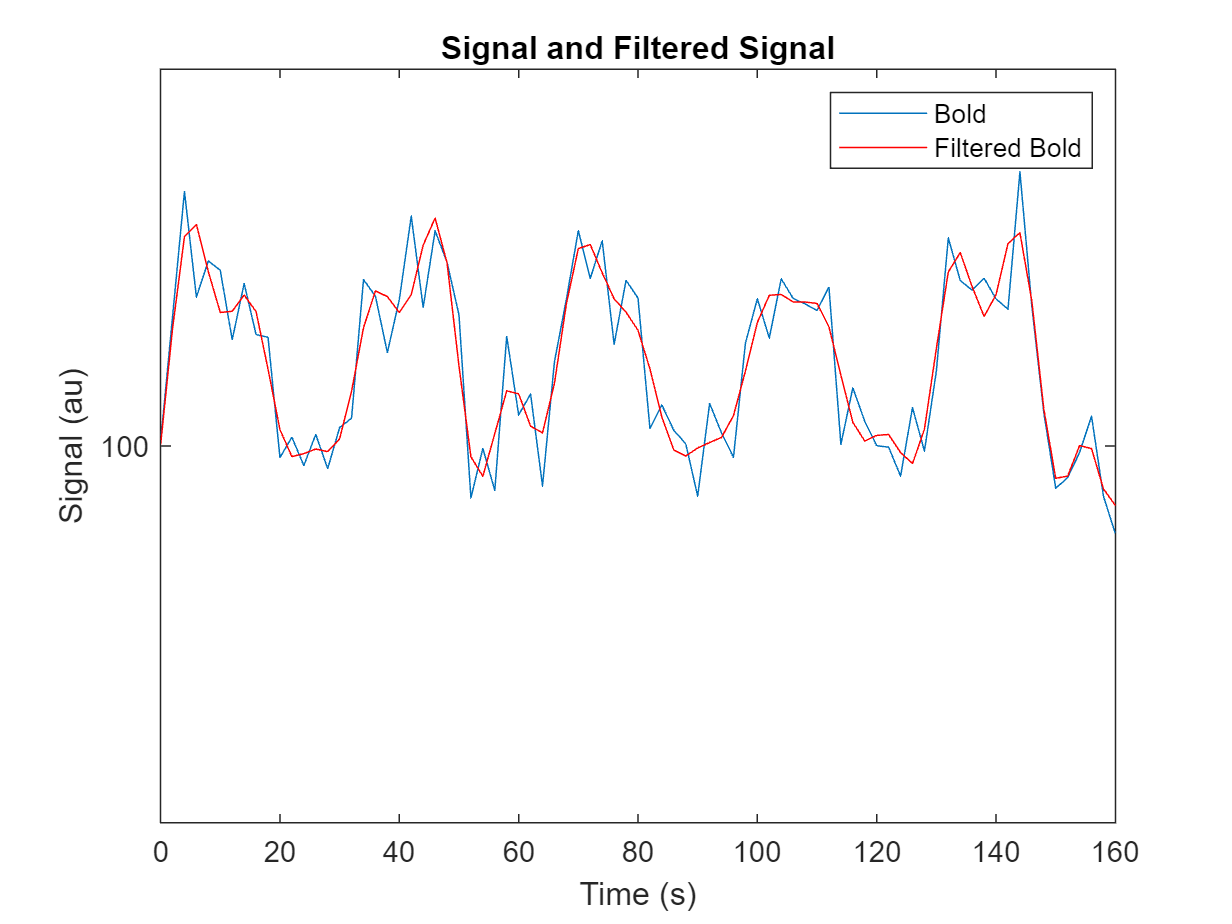

NOISECUTOFF = 0.1;
noise = frequency>NOISECUTOFF;
filteredFourierComponents = boldFourierComponents;
filteredFourierComponents(noise) = 0;
filteredBold = ifft(filteredFourierComponents);

clf;
plot(boldTime,bold);
hold on
plot(boldTime,filteredBold,'r');
title 'Signal and Filtered Signal'
legend('Bold','Filtered Bold')
xlabel 'Time (s)'
ylabel('Signal (au)');
set(gca,'YLim',[99 101],'YTick',100)

The filtered signal (red) is a smoothed version of the raw BOLD signal. In other words, the high frequency components, the noise, was removed and what remains is a smoothed BOLD signal. In terms of data analysis the difficult part is to decide where to cut off the signal, if you cut it off at too low a value you could be removing some of the signal together with the noise. 

Computationally there are two important things to take into account. First, note how I used the `frequency` variable to create the `noise` logical address. Becuase `frequency` was also defined for the duplicated frequencies (at locations in the `boldFourierComponents` vector above the location of the Nyquist frequency), the line that set all noise components to zero included those "negative" frequencies. If you forget to do this (or make any other change in the Fourier components that is not symmetric) the `ifft` will return complex numbers. Do **not** try to fix this by picking just the real part of the signal. If you get complex numbers, something is wrong and you have to fix it by making sure you're changing the Fourier components in a symmetric way. I think the easiest way to do this is to create the `frequency` vector with the correct values for all Fourier components and use this to generate the filter.

The seond important point is that filtering with a hard cut off is actually not recommended. To understand why, let's look at a simpler signal and its Fourier components.

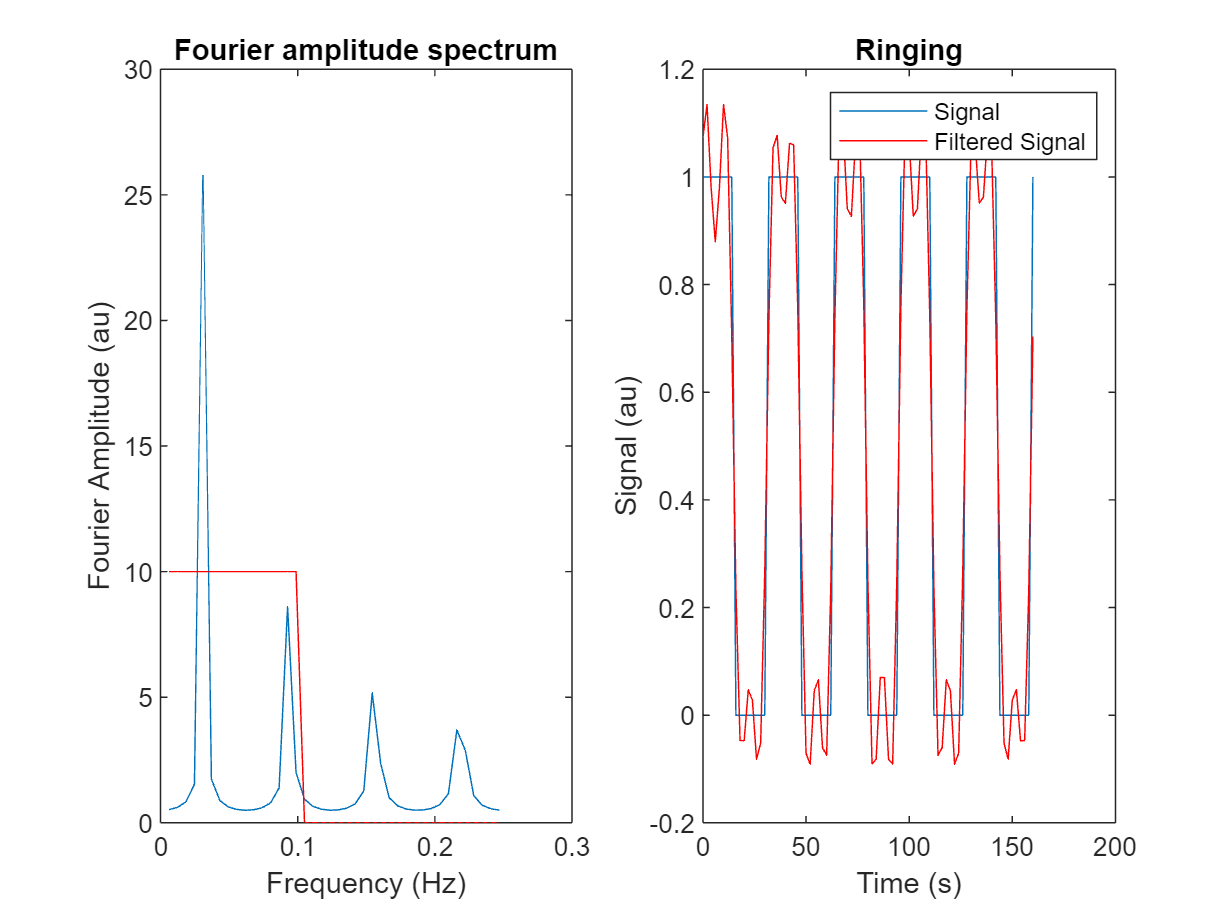

clf;
paradigmFourierComponents  = fft(paradigm);
halfAmplitudeSpectrum = abs(paradigmFourierComponents(keep));
R=1;C=2;
subplot(R,C,1)
plot(frequency(keep),halfAmplitudeSpectrum);
hold on
plot(frequency(keep),10*~noise(keep),'r')
xlabel 'Frequency (Hz)'
ylabel('Fourier Amplitude (au)');
title 'Fourier amplitude spectrum'

subplot(R,C,2);
plot(boldTime,paradigm);
hold on
filteredParadigmFourierComponents = paradigmFourierComponents;
filteredParadigmFourierComponents(noise) = 0;
filteredParadigm = ifft(filteredParadigmFourierComponents);
plot(boldTime,filteredParadigm,'r');
xlabel 'Time (s)'
ylabel('Signal (au)');
title 'Ringing'

legend('Signal','Filtered Signal')

This filtered signal (red) clearly does not look like a smoothened version of the original signal (blue). So even though it is true that the filtered signal no longer has the higher frequency components (we set those to zero), this does not look right in the time domain. This is an example of *ringing*: hard edges in a filter (i.e. the sharp transition from "signal" to "noise" in the red filter shown in the left panel) introduce periodic changes in the signal. The solution to this problem is to use a filter that changes gradually around the cutoff point. For instance, let' use a exponentially shaped filter:

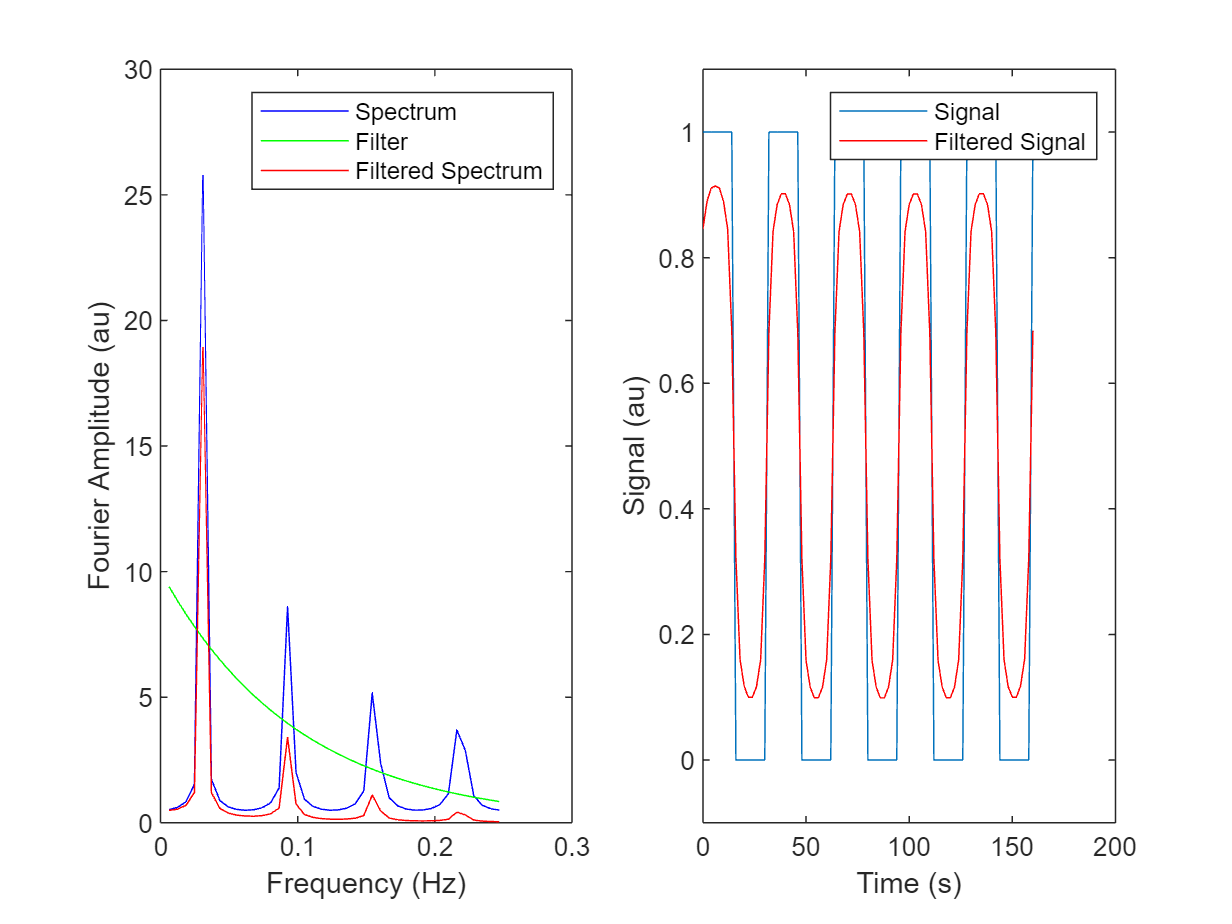

clf
paradigmFourierComponents  = fft(paradigm);
halfAmplitudeSpectrum = abs(paradigmFourierComponents(keep));
% Define a filter that drops off smoothly in the frequency domain:

filter = exp(-(frequency./NOISECUTOFF))';
% Apply the filter by multiplying in the Fourier domain.
filteredParadigmFourierComponents = paradigmFourierComponents.*filter;
% Recreate the filtered signal using the ifft
filteredParadigm = ifft(filteredParadigmFourierComponents);

R=1;C=2;
subplot(R,C,1)
plot(frequency(keep),halfAmplitudeSpectrum,'b');
hold on
plot(frequency(keep),10*filter(keep),'g')
plot(frequency(keep),abs(filteredParadigmFourierComponents(keep)),'r')
xlabel 'Frequency (Hz)'
ylabel('Fourier Amplitude (au)');
legend('Spectrum','Filter','Filtered Spectrum')

subplot(R,C,2);
plot(boldTime,paradigm);
hold on
plot(boldTime,filteredParadigm,'r');
xlabel 'Time (s)'
ylabel('Signal (au)');
ylim([-0.1 1.1])
legend('Signal','Filtered Signal')

On the left, you see the original spectrum in blue, the filter in green and the filtered Fourier spectrum in red. Applying the filter means that each Fourier component (blue) is multiplied by the value of the filter (green) at that frequency. The resulting Fourier amplitude spectrum is shown in red. You can see that the high frequency components are reduced a lot, but the low frequency components (leftmost peak) are reduced somewhat as well. This is due to the choice of our filter. We chose a filter that was smooth and dropped off very slowly, as a consequence it removed some noise, but also some signal. Designing the right kind of filter is an art (but there are many standard filters that have better properties than the one I used here). 

On the right you can see the consequences of the filtering after transforming the spectrum back to the time domain. Now the filtered signal looks a lot like a smoothed version of the original. You can see that some of the original signal has been removed because the overall amplitude of the red curve is smaller than the blue curve.

## Convolution, Smoothing

Filtering as we discussed it above is a muliplication of a Fourier spectrum with some function (the filter). This allows us to remove (or reduce) certain components. Convolution or smoothing achieves the same result without using the Fourier transform. An example may help to understand this:

First, consider a spike train as a sequence of zeros (no spike) and ones (spike). For data analysis it is often convenient to transform the binary spike train into a continuous function that can be interpreted as the instantaneous probability of observing a spike. The idea is that your observation of a spike at time t=10 is evidence that there was a high probability of a spike occuring at that time but this spike could have occurred a little earlier or later. We have to make some arbitrary assumptions about how much earlier or later, but a few ms seems a reasonable assumption. Essentially then what we want to do is to replace each spike with a Gaussian with a standard deviation of 15 ms whose peak coincides with the spike. First, we simulate a spike train:

DURATION = 1000; % Recording duration in ms.
NRSPIKES = 10; 
t = 1:DURATION;
spikeTime = sort(randi(DURATION,NRSPIKES,1));
spikeTrain = zeros(DURATION,1); 
spikeTrain(spikeTime)=1;

We can show these spikes on a time line:

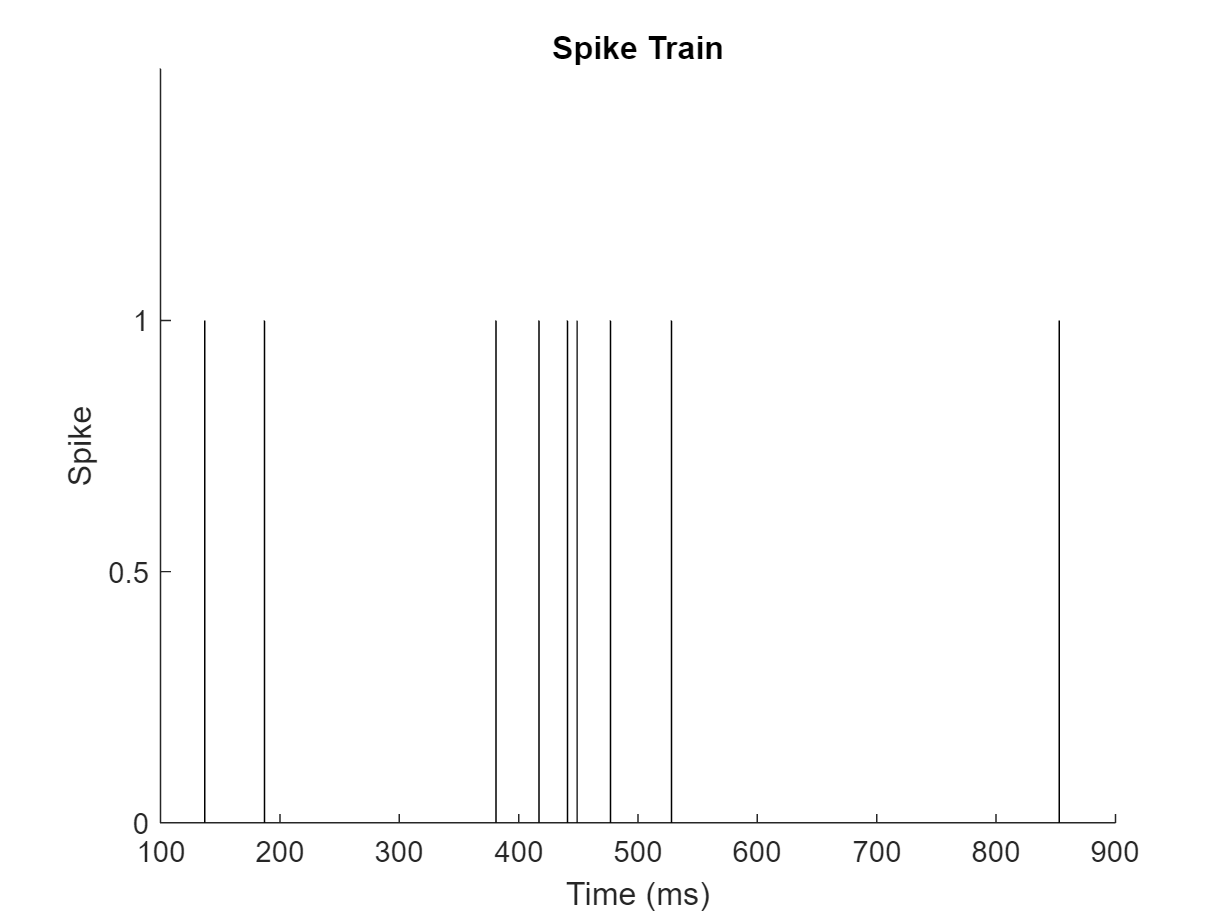

clf;hold on;
line([spikeTime'; spikeTime'],[zeros(1,NRSPIKES) ; ones(1,NRSPIKES)],'color','k')
ylim([0 1.5])
set(gca,'YTick',[0 0.5 1])
ylabel 'Spike'
xlabel 'Time (ms)'
title 'Spike Train'

Now we define the Gaussian filter. Note that we only use a subset of the times (`dt` ) because for our particular choice of `sigma` the Gaussian will be pretty much zero beyond that time. 

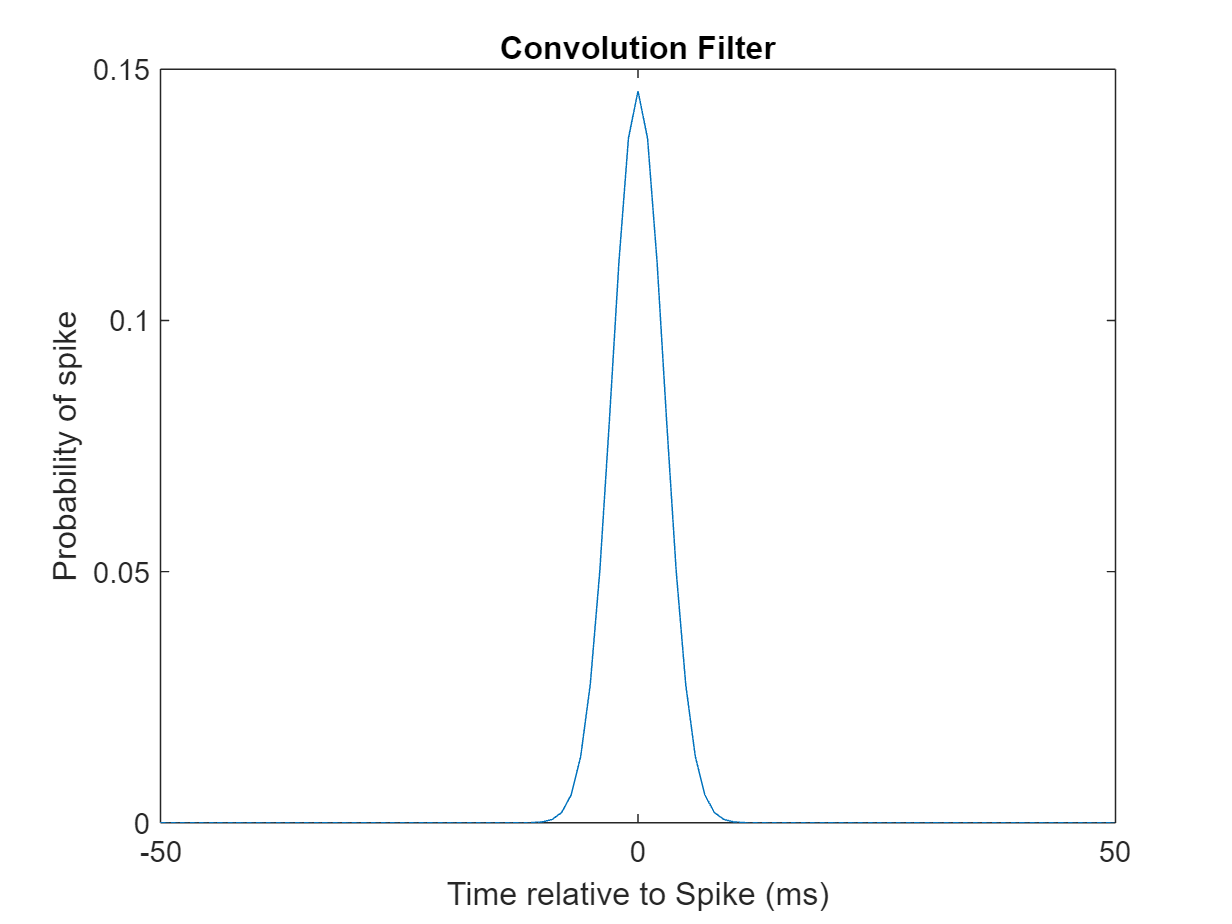

dt = -50:1:50;
sigma = 15;
gaussian = exp(-(dt.^2)/sigma);
gaussian = gaussian./sum(gaussian); % Make sure the total probablity is 1

clf;
plot(dt,gaussian)
xlabel 'Time relative to Spike (ms)'
ylabel 'Probability of spike'
title 'Convolution Filter'

The `conv` function essentially replaces each spike in `spikeTrain` with the `gaussian` and then adds all of those signals:

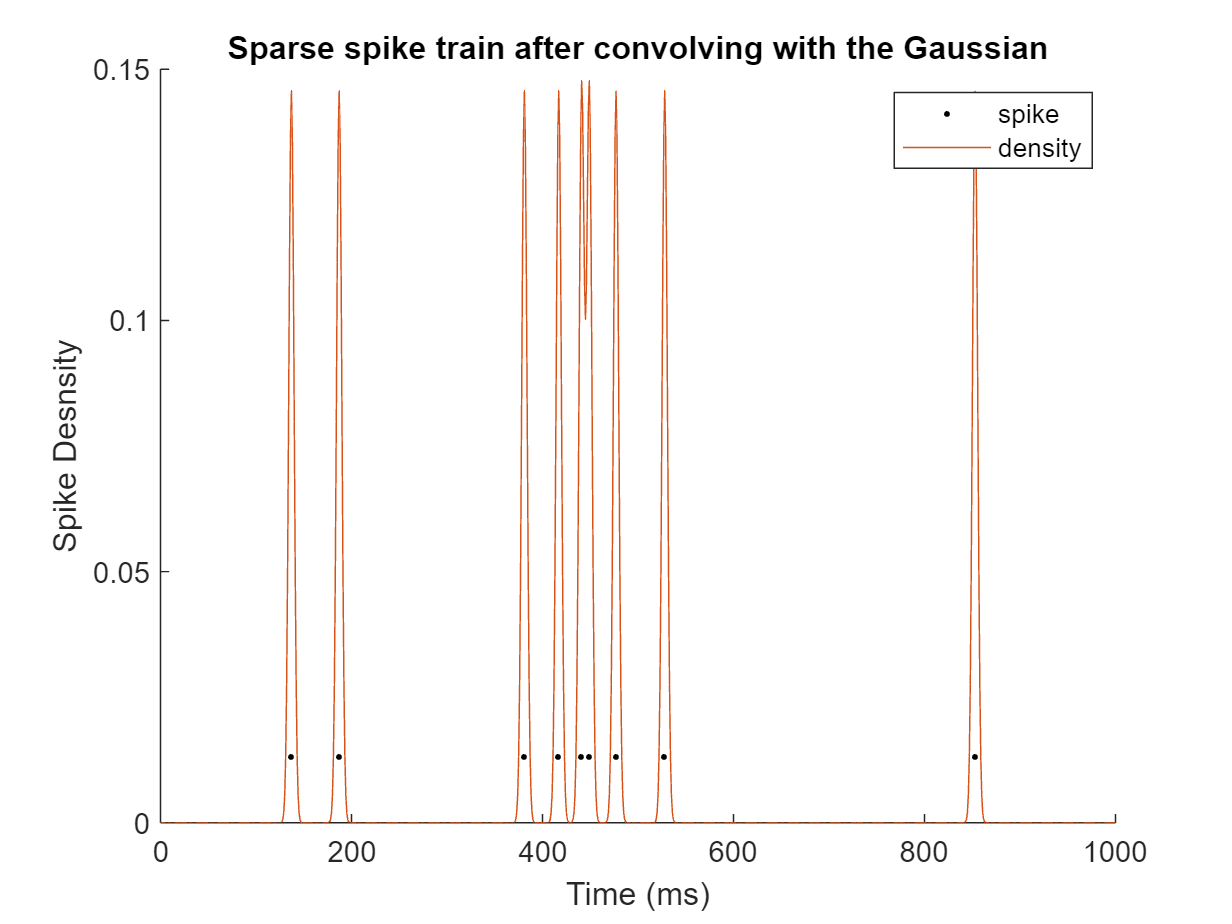

smoothTrain = conv(spikeTrain,gaussian,'same');

clf;
hold on; 
spikeY =prctile(smoothTrain,90);
plot(spikeTime,spikeY*ones(1,NRSPIKES),'.k')
plot(t,smoothTrain);
ylabel 'Spike Desnsity'
xlabel 'Time (ms)'
legend('spike','density')
title 'Sparse spike train after convolving with the Gaussian'

When spikes occur more closely together, the spike density gives a nice continuous measure of the probability of spike occurrence. In the figure below we simulate this by creating a spike count that goes up and down over a period of 1000 ms. 

With this you can see how the occurence of multiple spikes next to each other results in a high peak in the spike density. This smooth, continuous signal is often easier to analyze than the discrete spije times, and it may be a better reflection of the true underlying activity in the brain. (i.e. not what we happened to measure, but what we would have measured in some average sense if we could repeat the experiment 1000 times).

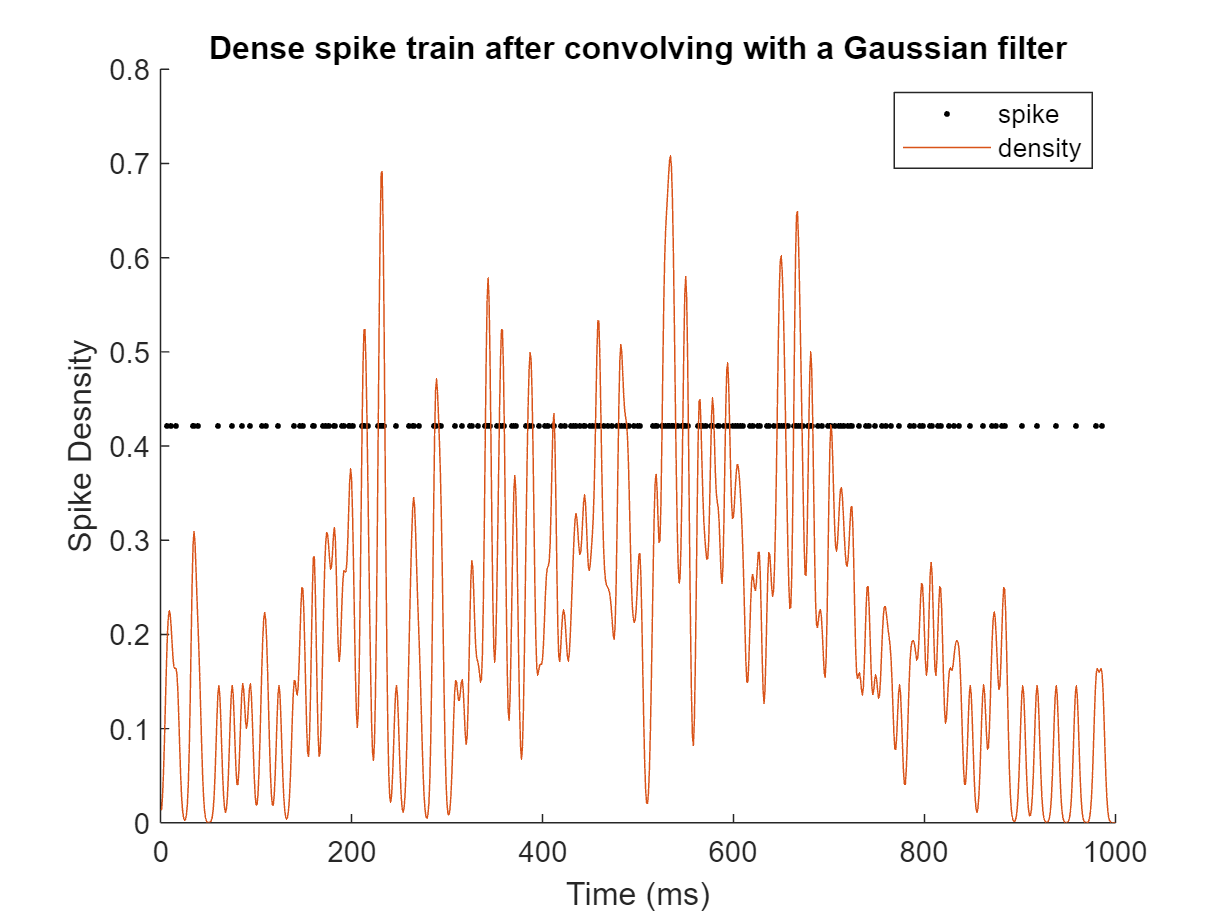

NRSPIKES = 250;  % Firing rate 
spikeTime = sort(round(DURATION/2+0.25*DURATION*randn(NRSPIKES,1)));
spikeTime(spikeTime<=0 | spikeTime>DURATION) = [];
spikeTrain = zeros(DURATION,1); 
spikeTrain(spikeTime)=1;
smoothTrain = conv(spikeTrain,gaussian,'same');

clf;
hold on; 
spikeY =prctile(smoothTrain,90); % A trick to get the spikes to show in a good location
plot(spikeTime,spikeY*ones(1,numel(spikeTime)),'.k')
plot(t,smoothTrain);
ylabel 'Spike Desnsity'
xlabel 'Time (ms)'
legend('spike','density')
title 'Dense spike train after convolving with a Gaussian filter'

### Terminology.

We took a signal (the spike train) and *convolved* it with a filter (the Gaussian). The result is a smoothed function. We used a binary signal here to illustrate what is going on (each unit of signal is replaced with the Gaussian), but the convolution procedure can be applied to any signal.

One way to think about this is that one unit of signal evokes a response that is 1 times the filter. If the signal is 2, we simply replace it by twice the filter. In this formulation the filter is called the temporal impulse response function: the response that each *impulse* (one unit of signal) generates.

This should remind you of the BOLD response: each unit of neural activity is assumed to generate something in the BOLD signal that looks like the hemodynamic response function. So, the assumption in most BOLD research is that the temporal impulse response function of the vascular system is the HRF. Or, one could say that the vascular system convolves neural activity with the HRF. 

Smoothing and convolution are two words for the same operation. Filtering as we discussed it above is in fact mathematically identical to convolution. Convolution of a signal with a filter in the time domain is equivalent to multiplication of the Fourier components of that sginal with the Fourier components of the filter (and then transforming back to the time domain).

This give us another way to understand what the spike density is. The Fourier transform of a Gaussian is a Gaussian in frequency space, with a peak at zero and a standard deviation of $1/\sigma$

So, when we did the convolution, we effectively multiplied components with a frequency near 0 with 1 and components with frequencies much larger than $1/\sigma$ with 0. This effecitvely removed high frequency components (i.e. this is a low-*pass* filter). As a result the rapid changes in the signal (the spikes) were removed and we were left with the smooth, slowly varying spike density. As an exercise, think about what the HRF does to neural activity in these same (Fourier) terms.

## Filtering with `filtfilt`

Matlab offers many more sophisticated methods to do filtering in the Signal Processing Toolbox. The approach is simiar to what we did above. First, you "design" a filter. The Gaussian filter we used above is a common one but there are many other possibilities.

The most flexible function to design a filter is `designFilt`. This function has a large number of parameters. They are all used to specify the shape of the filter: how fast it drops off, how low it goes, whether it lets high frequencies through or low frequecies etc. The possibilities are virtually limitless. Once you have a filter, you apply it to your signal using the `filter` or `filtfilt` methods. 

One important thing to take into account is that filters can introduce delays Think, for instance, about the HRF; a spike that occurs at t=0 will generate a peak activity at t~4s: the filter has introduced a delay. In signal processing you want to avoid such delays. The `filtfilt` method achieves this by first applying the filter forward in time and then backward in time. As a result whatever forward delay is introduced in the first pass is undone in the second (backward) pass. I cannot imagine any situation in neuroscience data analysis where you'd want to introduce delays with a filter. So if you use these filters, you should always use the `filtfilt` function.

Examples of filtering in data analysis:

- **Low-pas filters: remove high frequencies, keep the low frequencies.** When averaging BOLD signals across subjects we do not expect the voxels in one brain to match perfectly with the voxels in another subject's brain, but we do expect that they match on a scale of ~10 mm. Hence, before averaging across subjects we filter the BOLD signal (spatially!) with a Gaussian filter with a standard deviation of 10 mm. (Ideally with a three-dimensional Gaussian) This low-passed signal reflects a smooth, averaged BOLD response on a scale of several millimeter.

- **High-pass filters: remove low frequencies, keep the high frequencies.** Sometimes the lower frequencies in a recorded signal are the nuisance signals and we would like to filter them out. For this, we use a high-pass filter. For example, MRI scanner signals are known to drift over time. This is a slow variation that is not of interest. Before doing any analysis we take the time course in each voxel, and pass it through a high-pass filter. 

- **Band-pass filters: keep/reject a range of frequencies (within a "band").** A common example is the power-line artifact at 60 Hz (in the US). To remove this from an EEG recording, we create a band-reject (or 'notch') filter that removes frequencies near 60 Hz, but keeps the rest.

An example of high-pass filtering, using `filtfilt` First let's generate some data that have a contamination by a slow artifact (e.g. scanner drift) 

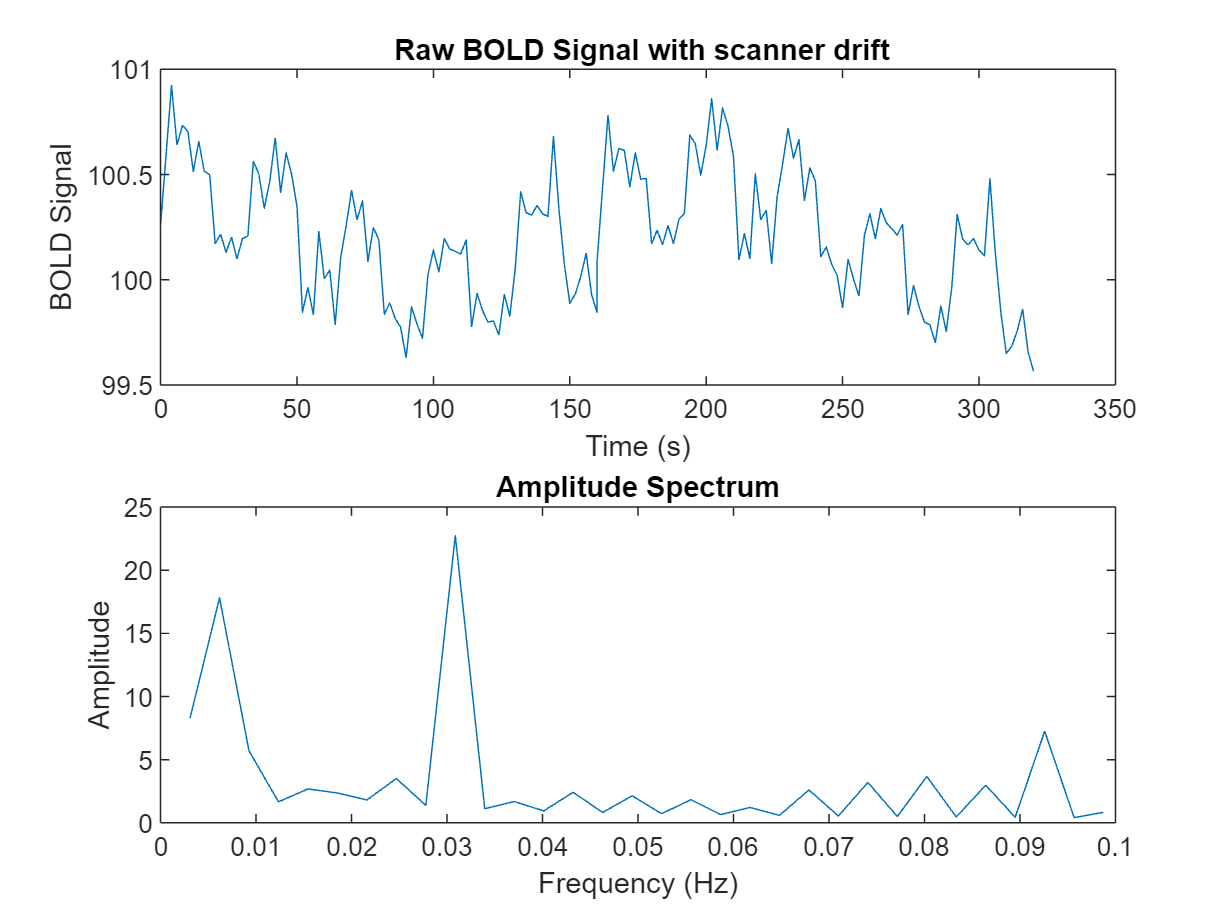

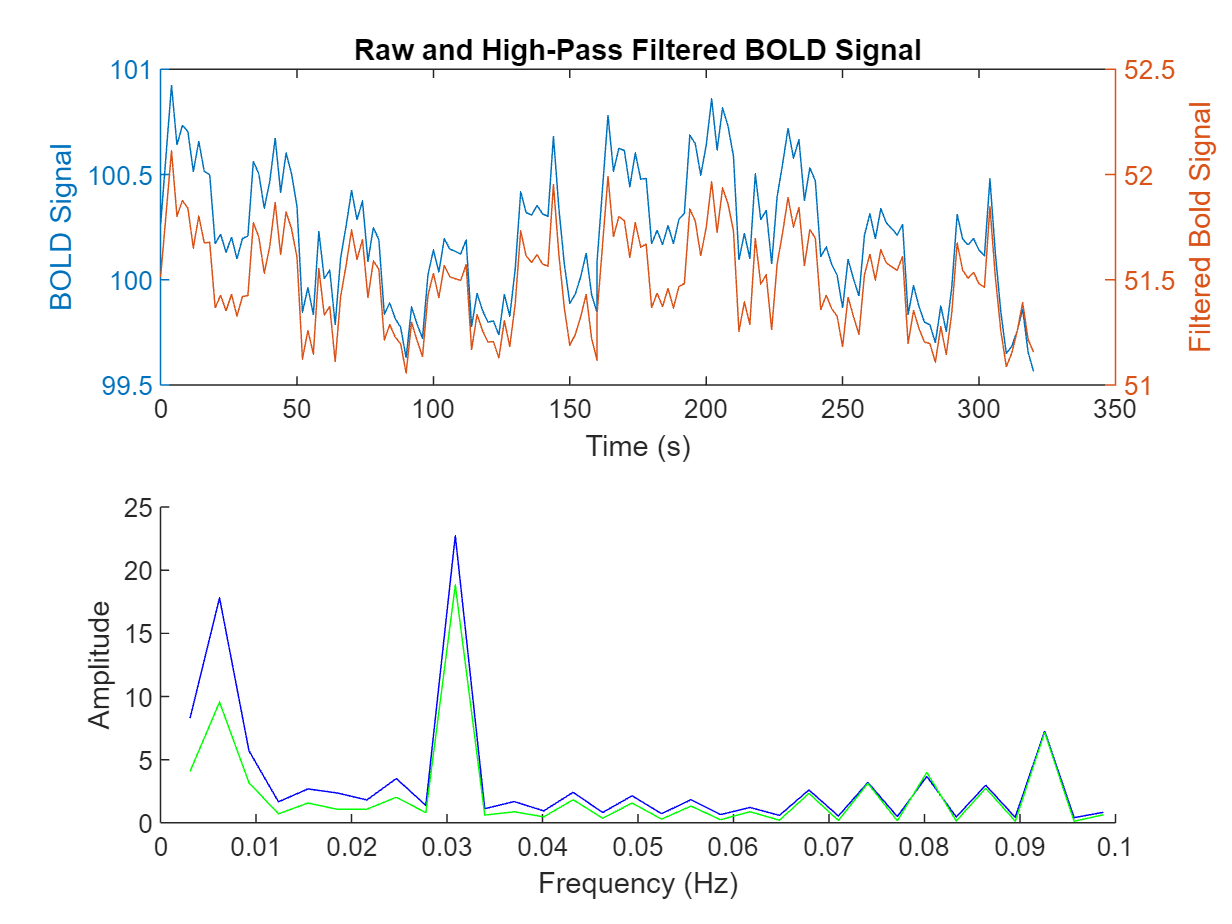

longBold        = cat(1,bold,fliplr(bold));
longBoldTime    = cat(1,boldTime,boldTime+boldTime(end));
driftAmplitude  = 0.25;
driftPeriod     = 200;
longBold        = longBold + driftAmplitude*cos(longBoldTime*2*pi/driftPeriod);


clf;
subplot(2,1,1);
plot(longBoldTime,longBold);
xlabel 'Time (s)'
ylabel 'BOLD Signal'
title ' Raw BOLD Signal with scanner drift'
subplot(2,1,2);
spectrum = abs(fft(longBold));
nrSamples= numel(longBold);
samplingRate = 1./TR;
if rem(nrSamples,2)==0
    % Even number of samples. Nyquist is the highest one
    frequency = [0 1:nrSamples/2 (nrSamples/2-1):-1:1]*samplingRate/nrSamples;  
    [~,highestFrequencyIx] =max(frequency);
else
    % Odd number of samples. Nyquist is not in the set.
    frequency = [0 1:(nrSamples-1)/2 (nrSamples-1)/2:-1:1]*samplingRate/nrSamples;
    [~,highestFrequencyIx] =max(frequency);
end
lowFrequencies = frequency >0 & frequency < 0.1;
plot(frequency(lowFrequencies ),spectrum(lowFrequencies ));
xlabel 'Frequency (Hz)'
ylabel 'Amplitude'
title 'Amplitude Spectrum'

The top panel shows that the signal is not as nicely regular as the original BOLD signal; sometimes the signal follows the paradigm nicely but in other ace-blocks the activity seems a lot lower. We suspect that there could be some contaminating low temporal frequencies. To investigate this, we use a spectral analysis and show this in the lower panel. The Fourier spectrum now has two peaks; one at the stimulus frequency and the other at `1./driftPeriod` . 

To remove this signal we assume that every sinusoid that is slower than `cutoff` is artifact and should be removed. We use a high pass filter:

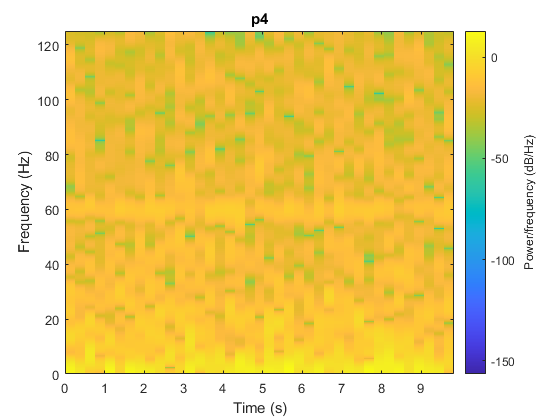

cutoff = 1./150;
highpass = designfilt('highpassfir', 'FilterOrder', 20, 'CutoffFrequency', ...
                        cutoff, 'SampleRate', samplingRate);
filteredBold = filtfilt(highpass,longBold);
filteredSpectrum = abs(fft(filteredBold));

clf
subplot(2,1,1);
yyaxis left
plot(longBoldTime,longBold);

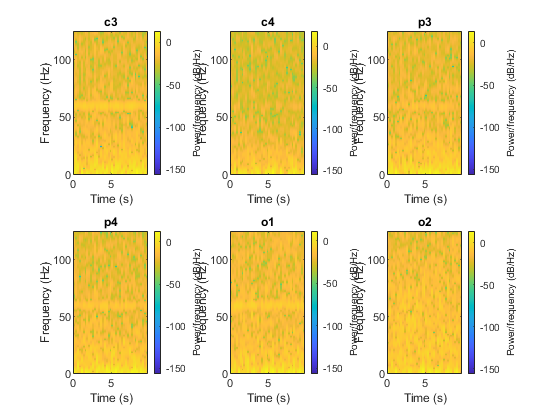

xlabel('Time (s)')
ylabel('BOLD Signal')
yyaxis right 
plot(longBoldTime,filteredBold);
ylabel('Filtered Bold Signal')
title 'Raw and High-Pass Filtered BOLD Signal'



subplot(2,1,2);
hold on
plot(frequency(lowFrequencies ),spectrum(lowFrequencies ),'b');
plot(frequency(lowFrequencies ),filteredSpectrum(lowFrequencies ),'g');
xlabel 'Frequency (Hz)'
ylabel 'Amplitude'

Note a couple of interesting things here.r

- The top panel shows that the filtered BOLD signal (red) seems to vary less on the slow (drift) time scale. The Fourier plot below confirms this: the Fourier amplitude at 0.005 in the filtered signal (red) is less than that in the original BOLD signal (blue).

- The mean signal has been reduced as well (compare the scale on the left axis of the panel with that of the right axis). This is expected as the mean signal is the Fourier component at zero frequency, which is below the cut-off frequency hence a high-pass filter attenuates it. 

- Filtering is not an all-or-nothing phenomenon: the drift component is reduced, not removed . This is a consequence of using filters that are physically realizable (i.e. you could construct some electronics that performs exactly this filtering operation on a real, continuous signal). In principle we could remove the entire drift component in Matlab, but this would have undesirable consequences for the filtered signal (e.g. the ringing demonstrated above). 

- Filtering can remove artifacts but also signal. As you can see from the Fourier spectrum, the green curve's peak at the stimulus frequency (0.03 Hz) is also reduced. This means that our high-pass filter has removed some signal. This is, again, the consequence of using physically realizable filters and cannot really be avoided. To get an idea of how much signal will be removed, and how much artifact, you can use the `fvtool` with the `highpass` filter. The `fvtool` will visualize the transfer characteristics of the filter. You should play around with the `'FilterOrder'` and other parameters to design better filters. 

One final note, because filters cannot discriminate between signal and noise, your experimental design should try to separate these components of your recordings as much as possible. For instance, in a fMRI block design your blocks should be long enough so that their fundamental frequency is far from the breathing frequency (which causes BOLD signal variation). The example above shows that if you fail to do this, then filtering cannot help you.

## Spectrograms

Fourier analysis gives you one answer about the spectral content of your entire signal. For long recordings this is not particularly useful. The power in some frequency band, for instance, could wax and wane over time(e.g. alpha band power in EEG with drowsiness, gamma band power in the LFP with attention). A standard Fourier analysis would just give you one measure for alpha power. 

A straightforward way to solve this issue is to apply the Fourier transform only to a subset of the data (a window) and then shift this window in time. This is called the short-time Fourier Transform (STFT) and instead of a spectrum it results in a spectrogram which shows the change in power/amplitude at each frequency over time.

There are few important things to consider:

- If your window is short you cannot estimate the power in low frequency bands. From the discussion of the FFT you know that the lowest frequency in the FFT fits exactly once in the signal length. In other words, a 100 ms window allows you to estimate 10 Hz (alpha) but not the power in lower frequency bands. Similarly, for power in the gamma frequency bands (40 hz), your windows need to be at least 1./40 =25 ms long. In practice you should have several multiples of the minimal window size.

- It is not a good idea to simply pull out a section of the data from the signal and pass that to the `fft` function. Instead, these sections should be *windowed* which means that you take the product between the signal and a bell-shaped function centered on a certain time point, and perform the FFT on the product. In the Matlab Signal Processing Toolbox the `spectrogram` function allows you to specifiy which window to use for this purpose. Common windowing functions are the `hamming` or `hann` window. 

- An advanced variant of this windowing procedures uses more than one window (also called a taper) and then averages over those tapers. The disadvantage of this multitaper approach is that you have more choices to make (whch tapers, how many?) and that these choices often need to be different for low and high frequency bands. Although there are probably good reasons to use multitaper spectral analysis, its complexity is a downside. If you want to explore this method, you can start with the `pmtm.m` function of the Signal Processing Toolbox, and there is a freely available toolbox called [Chronux](http://chronux.org/) that specializes in multi-taper spectral analyses.  

- You may also come across three alternative methods that estimate power/amplitude in each frequency band as it changes with time: Hilbert analysis, Wavelet analysis, and Matching Pursuit. Under most circumstances that matter to Neuroscientists these methods are equivalent (by which I mean that whatever esimate you can get from Wavelet analysis, you can also get from STFT or Hilbert analysis. See Bruns, J Neurosci Methods 137 (2):321-332 (2004) for a proof). 

For simplicity I'll focus on the STFT here. 

Let's determine a spectrogram for the eeg data. I picked the 'p4' electrode channel and chose windows that are 0.25s wide and non-overlapping.

load eegData
samplingFrequency  = 250; %Hz
windowWidth =0.25; % in s 
nrSamplesPerWindow = round(windowWidth.*samplingFrequency);
overlap = 0; 
nrSamples= size(eegData,1);
channelStay = strcmp(eegChannels,'p4');
clf
spectrogram(double(eegData(:,channelStay)),nrSamplesPerWindow,overlap,nrSamples,samplingFrequency,'yaxis');
title('p4')

There isnt much interesting structure over time here, except that the 60 Hz artifact seems to get stronger during the recording and then decay again. To see if this is real, we can see what the other channels do.

clf

rPearson = 0.3438

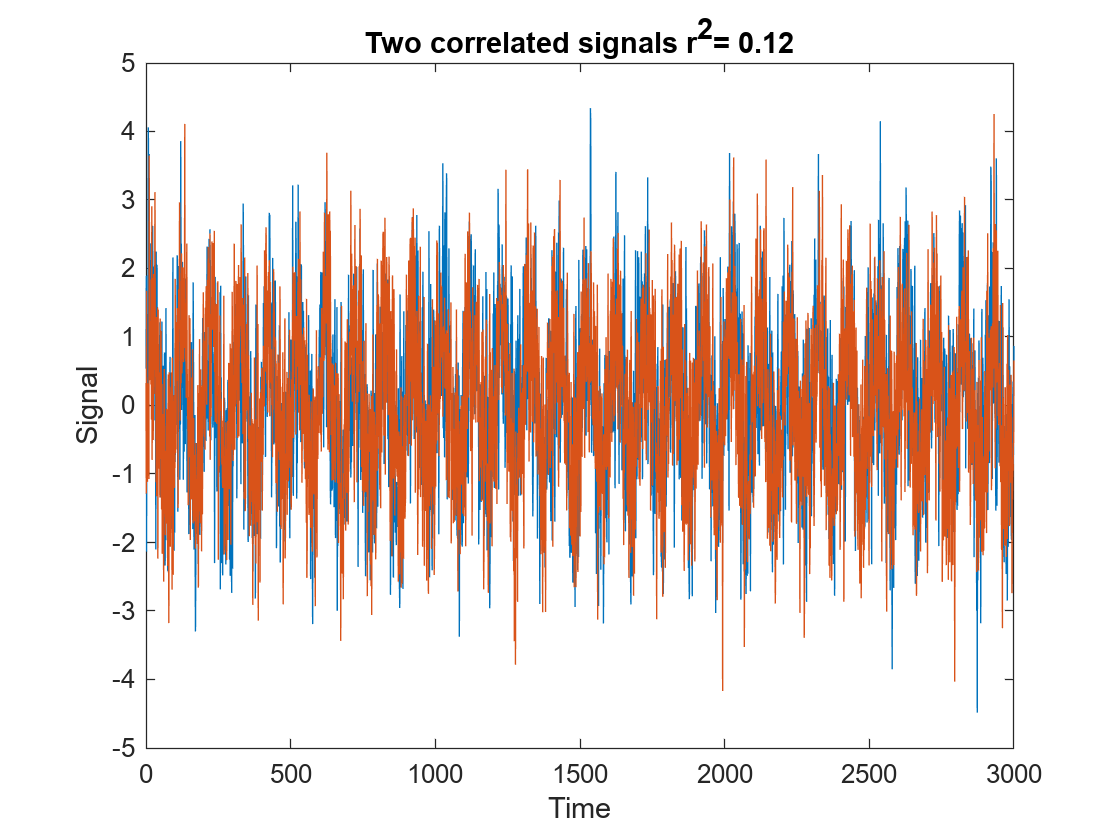

for c=1:size(eegData,2)

    subplot(2,3,c)
    spectrogram(double(eegData(:,c)),nrSamplesPerWindow,overlap,nrSamples,samplingFrequency,'yaxis');
    title(eegChannels{c})
end

rhoSpearman = 0.3512

It seems that p3 has a similar non-stationary artifact. Although this is not a particularly interesting finding, it is an example of something that standard Fourier analysis would not be able to pick up. Hopefully you'll find more interesting effects in your data!

## Coherence

Often we want to know how one signal (recorded in brain area X) relates to another signal (recorded in brain area Y). 

### Correlation

The simplest measure, used in resting state functional connectivity analyses, for instance, is the correlation. This is one number that quantifies how much signal X and signal Y go up and down together. A correlation of +1 means that the two signals always go up and down together, 0 means that there is no relation, and -1 means that whenever X goes up Y goes down.

rng default;

tauKendall = 0.2357

t= (0:1:3000)'; % 3 second of data
freq = 10;  % Let the signal oscillate at 10 Hz.
x = sin(2*pi*freq*(t/1000)) + randn(size(t)); % Add noise
y = sin(2*pi*freq*(t/1000)) + randn(size(t));  % Add separate noise
figure;
plot(t,x);
hold on
plot(t,y)
xlabel 'Time'
ylabel 'Signal'
rPearson = corr(x,y,'type','pearson')
title (sprintf('Two correlated signals r^2= %3.2g',rPearson^2))


The correlation coefficient r has a nice intepretation; $r^2$ is the fraction of the variance that x explains about y.  In other words, in this example knowing x, we can predict ~10% of y.

This Pearson correlation works well if you are willing to assume that x and y are linearly related. But if this is not likely the case, or if there are many outliers in x or y, then you can use correlation measures that do not make this assumption and often generate a more robust estimate:

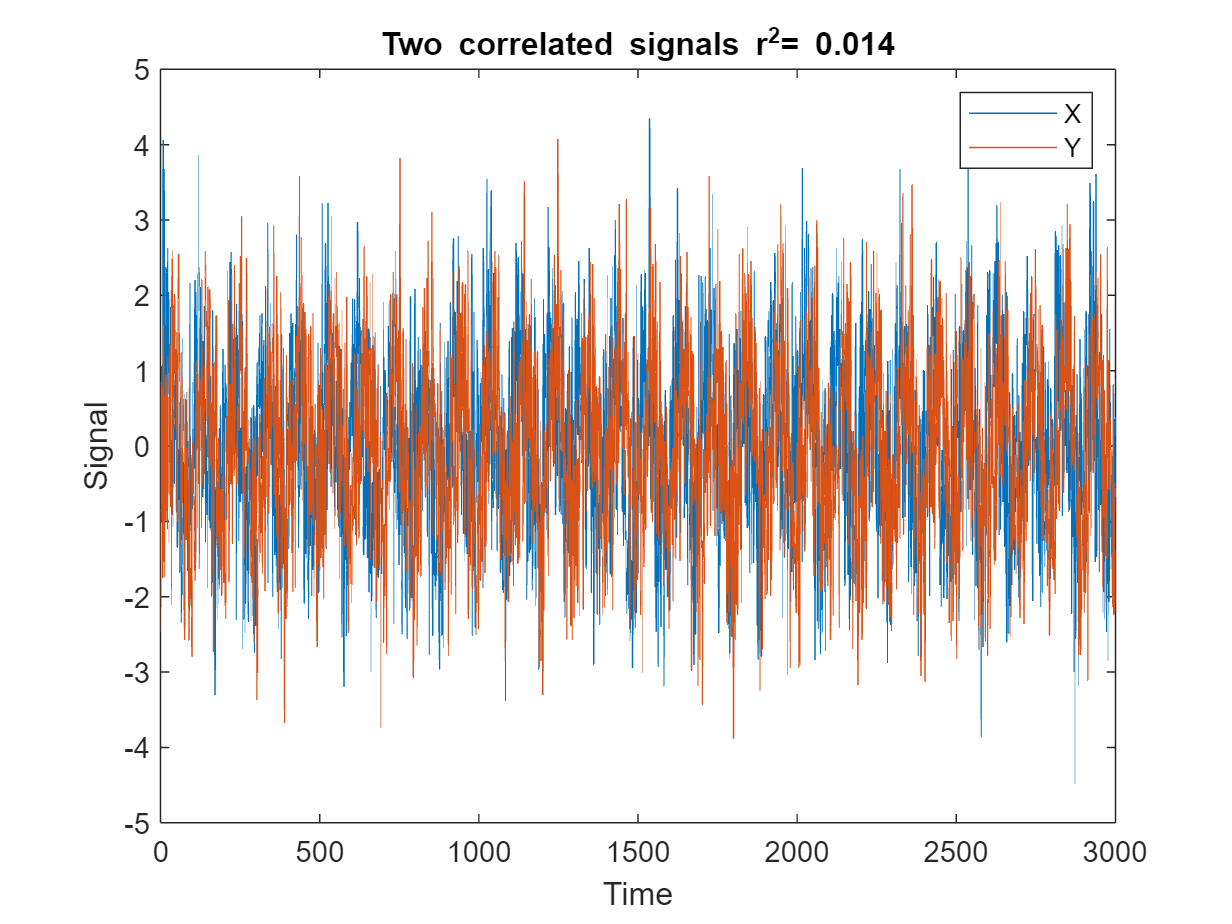

rhoSpearman =  corr(x,y,'type','Spearman')

tauKendall=  corr(x,y,'type','Kendall')


But for these well-behaved samples, the different methods don't make much of a difference. 

In this example we compared signal x and signal y at the same time - as they were observed. If these were real brain signals from different areas, one might expect that activity in area y lags behind area x.

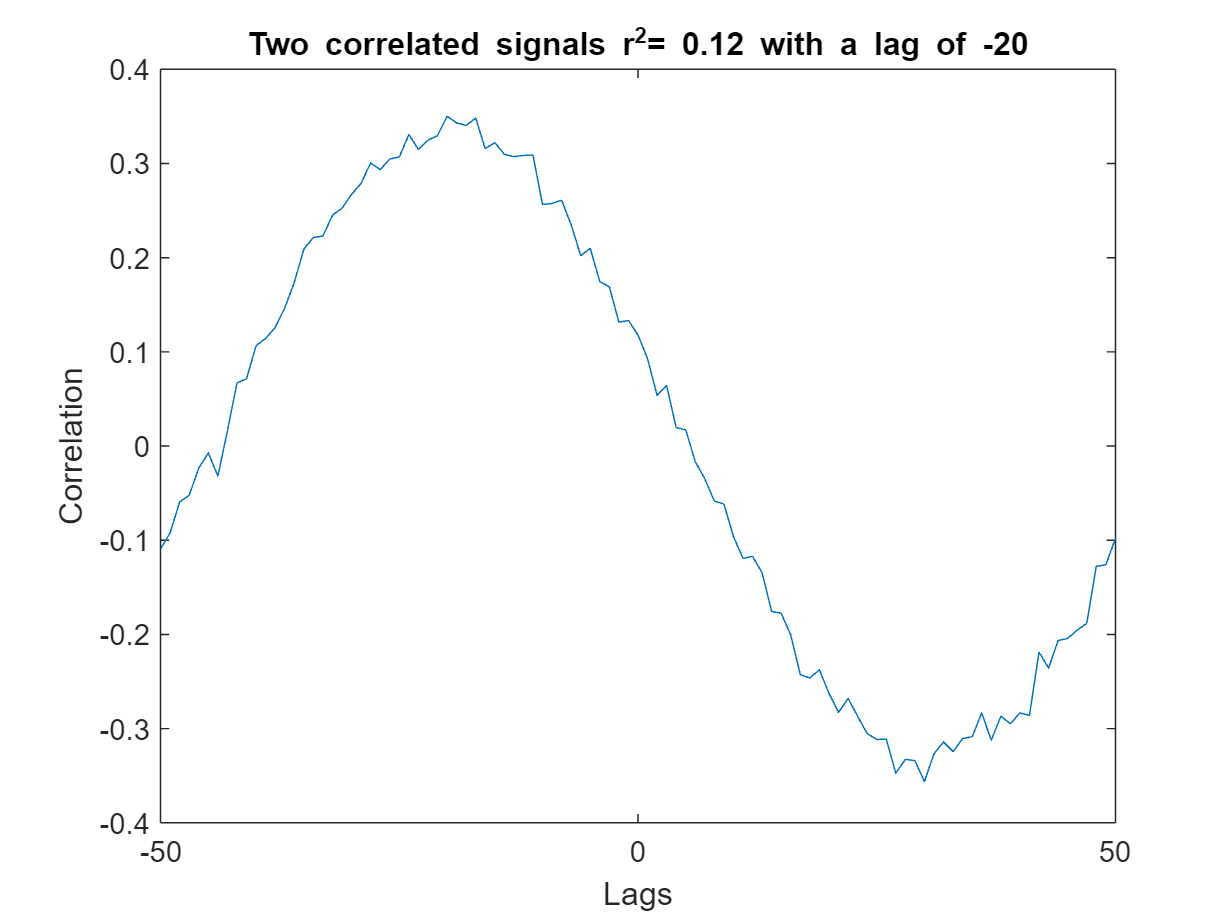

delay = 20; 
y  = sin(2*pi*freq*(t-delay)/1000) +randn(size(t)); % Delay the y signal
figure;
plot(t,x);
hold on
plot(t,y)
xlabel 'Time'
ylabel 'Signal'

rPearson = corr(x,y,'type','pearson');
title (sprintf('Two correlated signals r^2= %3.2g',rPearson^2))
legend('X','Y')

Now x only explains a very small fraction of the variance. Obviously that is not quite correct as we can see that the signals are equally correlated, just delayed. We can capture this with the cross-correlation, which essentially computes the correlation while shifting one of the signals in time. 

maxLag = 50; % Limit the number of lags to 50 ms
[xc,lags] =xcorr(x,y,maxLag,'normalized');
clf;
plot(lags,xc)
xlabel 'Lags'
ylabel 'Correlation'
[maxPearson,maxCoherenceIndex] = max(xc);
lag = lags(maxCoherenceIndex);
title (sprintf('Two correlated signals r^2= %3.2g with a lag of %3.3g',maxPearson^2,lag))

This shows how the cross-correlation was able to find that x and y are really correlated (with ~13% variance explained) and a lag of ~20 ms  (close to the simulated `delay` of 20 ms).

### Coherence

Coherence is conceptually similar to correlation, with the main difference that it is calculated separately for each Fourier component in the signals x and y. Where correlation just gives one overall number that quantifies how strongly x and y are linked, coherence gives one number per frequency. 

In Matlab you can compute coherence, using `mscohere. `Note that mscohere outputs the magnitude squared of the coherence, so it is analogous to $r^2$ rather than $r$.

The most common way to compute coherence is by using a sliding window over the time series, compute coherence in each, and then average over the time windows. While this is not necessary, it improves the reliability of your estimates (at the cost of time resolution). Chosing the right window takes some care; you want at least a few cycles of the frequencies of interest in one window (to get better spectral resolution), but also you want as many repeated measurements across your entire time series as possible (to get less noisy estimates of the average). 

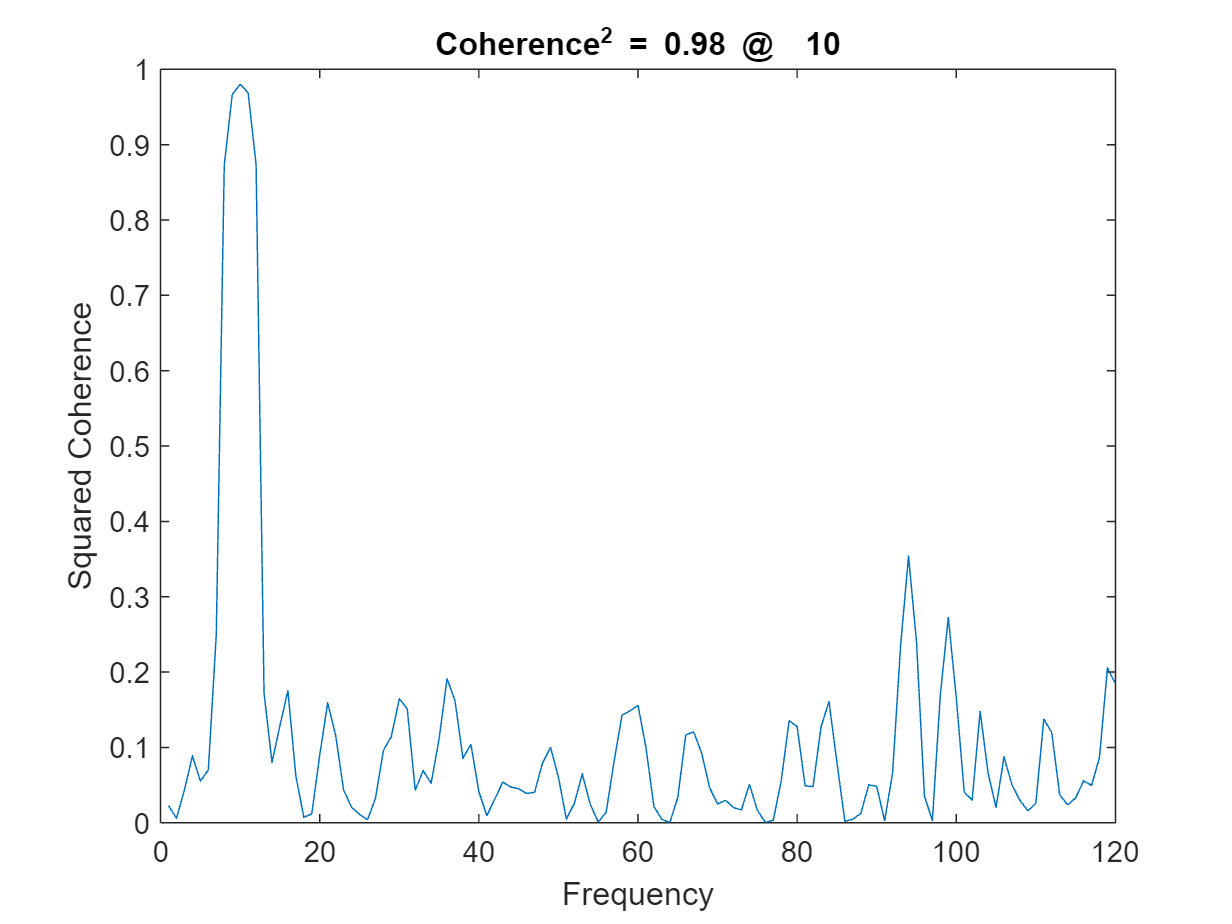

% Set some of the options of the mscohere function:
window = 500;  % Use windows of this number of samples
overlap  = 250; % Overlap windows by this many samples

targetFrequencies = 1:120; % Estimate coherence at these frequencie
samplingRate = 1000;
[coherence] = mscohere(x,y,window,overlap,targetFrequencies,samplingRate);
clf;
plot(targetFrequencies,coherence);
xlabel 'Frequency'
ylabel 'Squared Coherence'

[maxC,maxCoherenceIx] =max(coherence);
title (sprintf('Coherence^2 = %3.2g @ %3.2g',maxC,targetFrequencies(maxCoherenceIx)))

This shows that the coherence is nearly 1 and peaks at the 10 Hz frequency; as expected for our simulated signals. 

Note that this analysis did not suffer from the lag between x and y; because the coherence is computed in the Fourier domain, lag does not affect the magnitude. If you want to know the lag at which the coherence was maximal you have to compute the cross-spectral density (mscohere computes that internally to give you the coherence, but it does not return that to the command line, so we have to compute it again,)

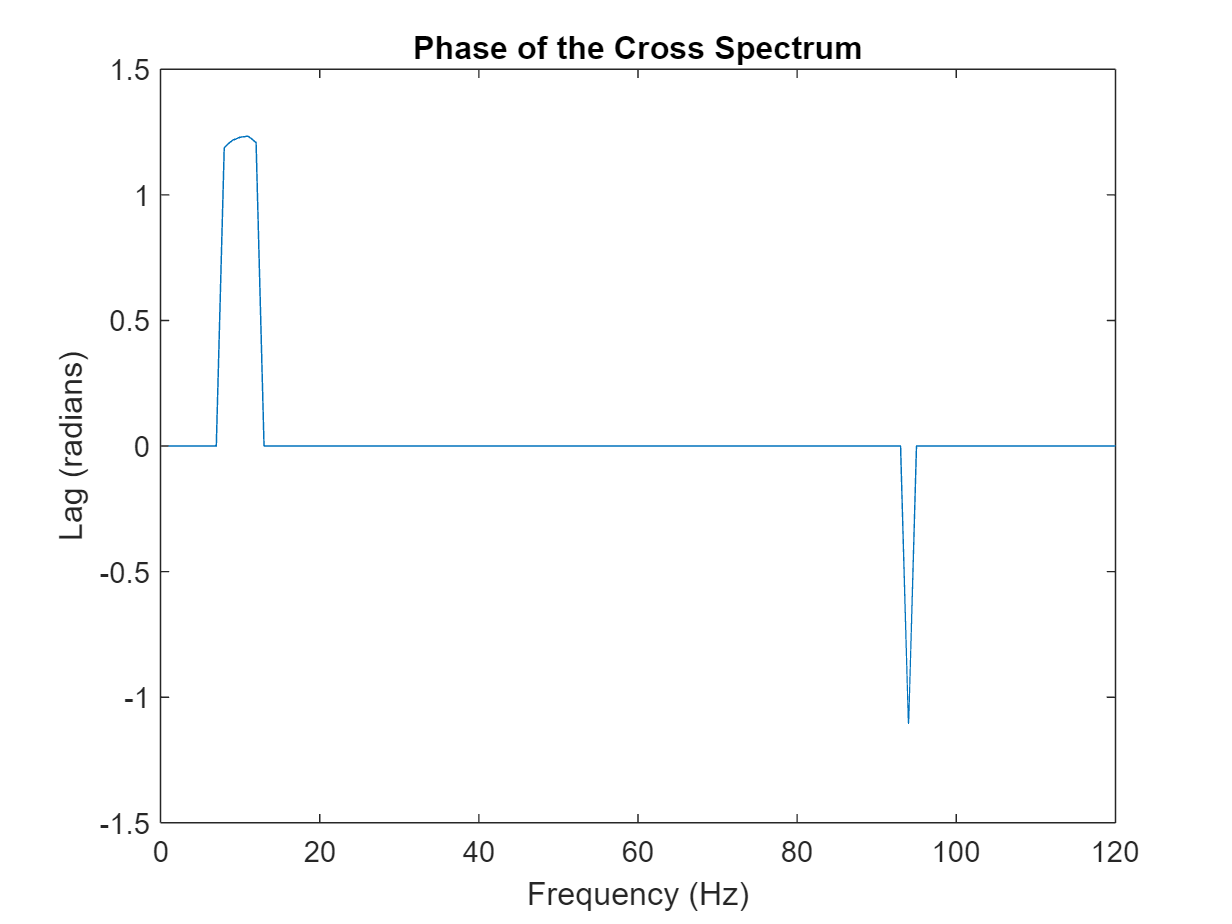


[crossSpectralDensity] = cpsd(x,y,window,overlap,targetFrequencies,samplingRate);

% Phase is not really defined when there is no coherence, so clean up:
coherenceThreshold = 0.3;
crossSpectralDensity(coherence<coherenceThreshold) = 0;
% Show phase 
plot(targetFrequencies,angle(crossSpectralDensity))
title('Phase of the Cross Spectrum')
xlabel('Frequency (Hz)')

timeLag = 19.5688

ylabel('Lag (radians)')

% Get the phase of the cross-spectrum at the peak of the coherence.
phaseLag = angle(crossSpectralDensity(maxCoherenceIx));
% Translate the phase lag to a time lag in milliseconds 
oneCycleDuration = (1/targetFrequencies(maxCoherenceIx));
fraction = phaseLag/(2*pi);
timeLag = 1000*fraction*oneCycleDuration

As you can see the time lag between the signals was correctly identified as 20 ms. 

### Multiple rhythms 

You can calculate coherence between any two signals, but its benefits (as compared to a correlation) become clearest when those signals have multiple ongoing rhythms that are coupled in different ways. 

Here we concoct signals from brain areas that are coupled strongly in the alpha band and weakly in the gamma band, 

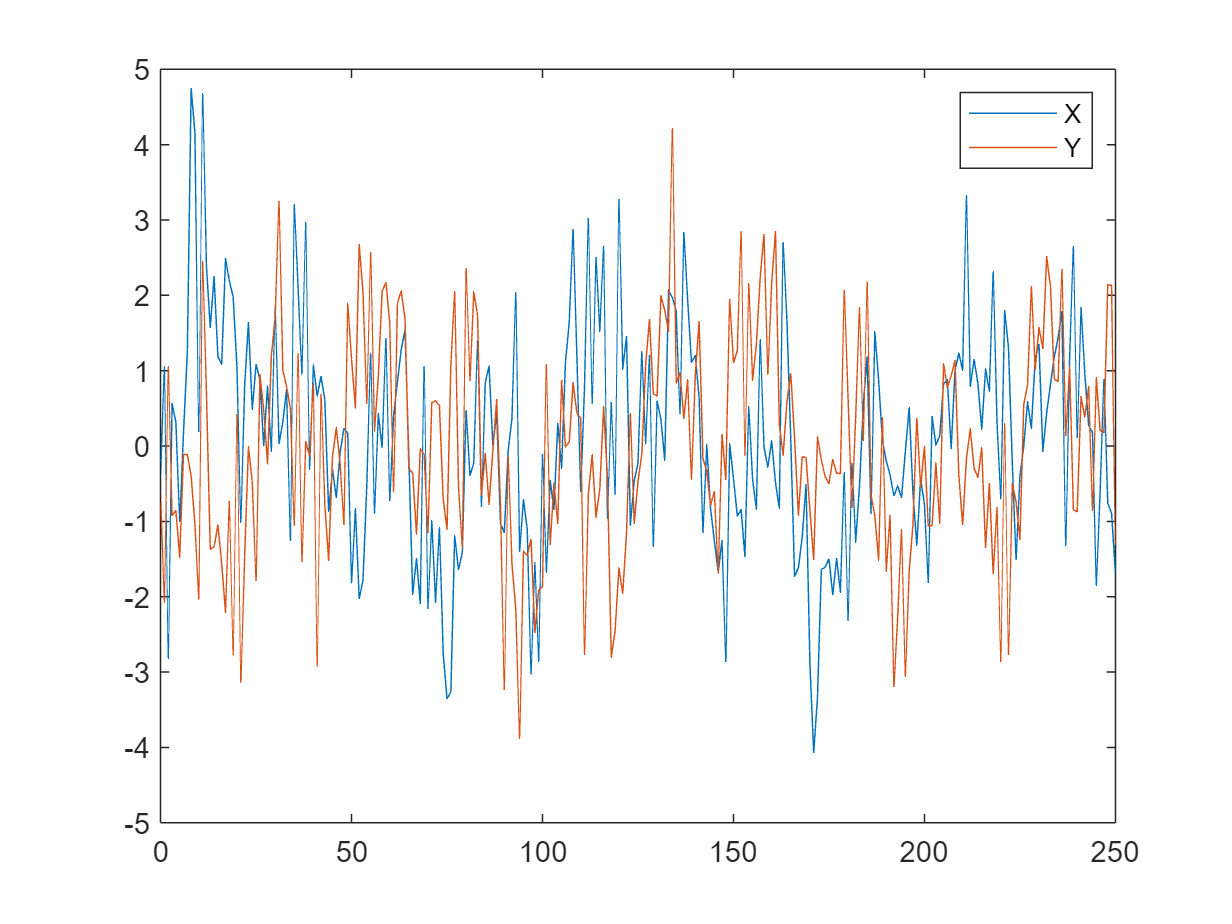

rng default;
alpha = 10;  % 10Hz alpha 
alphaLag = 30; % Lagging in Y
gamma = 40;  % 40 hz gamma 
gammaLag = 5; % Lagging in X
% Signal in x is the sum of an alpha rhyth, and a delayed (compared to y)
% gamma rhythm.
x = sin(2*pi*alpha*(t/1000)) + sin(2*pi*gamma*((t-gammaLag)/1000))+ randn(size(t));
% In y we create a delayed alpha rhythm, plus a gamma rhytm where the famma
% frequency oscillates a little over time (this reduces coherence)
gammaNoise = (1+0.004*sin(2*pi*alpha*t/1000));
y = sin(2*pi*alpha*(t-alphaLag)/1000) + sin(2*pi*gamma.*gammaNoise.*t/1000) + randn(size(t));
% Show the signals. 
figure;
plot(t,x);
hold on;

plot(t,y)
legend('X','Y')
xlim([0 250]) % Zoom in for clarity

Let's see how to extract that interarea coupling. In this case we'll use a slightly shorter window (250 ms; still large enough to have 2.5 cycles of the low frequency of interest) and use a smooth (hanning) window to improve spectral estimates. 

% Compute Coherence
% Set some of the options of the mscohere function:
window = hanning(250);  % Use a hanning window
overlap  = 125; % Overlap windows by this many samples
targetFrequencies = 1:120; % Estimate coherence at these frequencie
samplingRate = 1000;
[coherence] = mscohere(x,y,window,overlap,targetFrequencies,samplingRate);
clf;
yyaxis left
plot(targetFrequencies,coherence);
xlabel 'Frequency'
ylabel 'Squared Coherence'


For simplicity, we determine coherence at exactly alpha and gamma frequencies. In practice, you'd find the location of the peak in a window around those frequencies.

alphaCoherence = coherence(targetFrequencies==alpha);
gammaCoherence = coherence(targetFrequencies==gamma);
title (sprintf('Coherence^2 = %3.2g @ alpha and  %3.2g @ gamma',alphaCoherence,gammaCoherence))


Following the same approach as befofre, we estimate the lags:

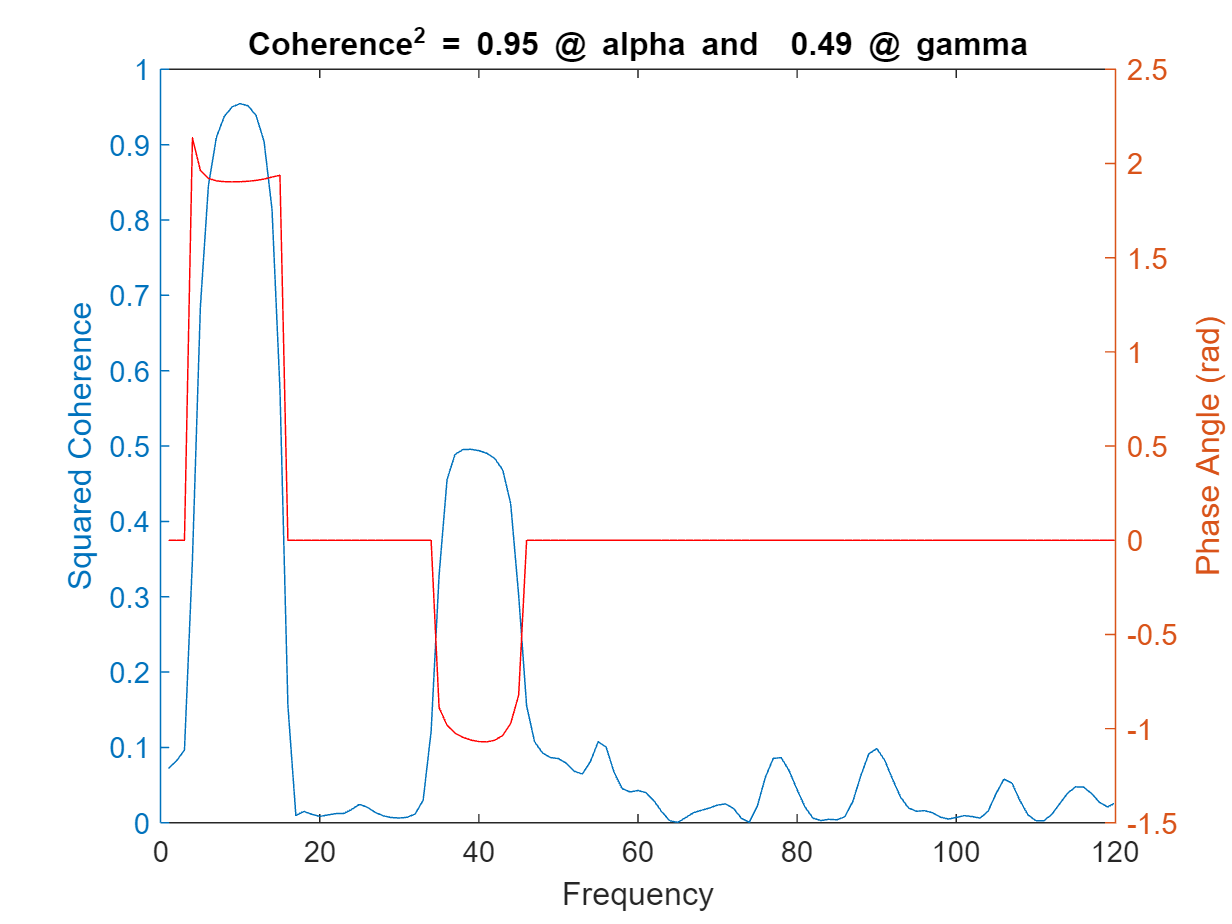

% Re-compute the cross spectrum 
[crossSpectralDensity] = cpsd(x,y,window,overlap,targetFrequencies,samplingRate);
coherenceThreshold = 0.3;
crossSpectralDensity(coherence<coherenceThreshold) = 0;
hold on 
% Show phase in same figure
yyaxis right
plot(targetFrequencies,angle(crossSpectralDensity),'r')
ylabel 'Phase Angle (rad)'


% Determine lag at each of the peaks
freqOfInterestIx = ismember(targetFrequencies,[alpha gamma]);
phaseLag = angle(crossSpectralDensity(freqOfInterestIx));
% Translate the phase lag to a time lag in milliseconds 
oneCycleDuration = (1./targetFrequencies(freqOfInterestIx));
fraction = phaseLag/(2*pi);
timeLag = 1000*fraction.*oneCycleDuration

timeLag =    30.2906   -4.2531


As you can see the coherence analysis did recover the salient parts of the coupling between the areas: strong coupling in the alpha band with a lag (in area y) of ~30 ms, weaker coupling with a lead of ~4 ms in the gamma band. 